# System Identification (SI) for Narnia Testing Chamber

clear; clc;
data_dir = "C:\Users\hdt.OJ\OneDrive - OJ Electronics A S\Thesis\report\data\Test 6";

## Active cooling data

baselog_AC_file = data_dir + "\BaseLog-2024-03-19T152053-ActiveCooling.csv";
baselog_AC_data = loadDataSource(baselog_AC_file);

modblog_AC_file = data_dir + "\ModbusGUI-Log-2024-03-19T152042-ActiveCooling.csv";
modblog_AC_data = loadDataSource(modblog_AC_file);
modblog_AC_data.regulation_relay_state(:) = 0;
AC_data = innerjoin(modblog_AC_data,baselog_AC_data,"LeftKeys","TimeStamp","RightKeys","timestamp")

AC_data = 67174×30 table
           TimeStamp           regulation_relay_state    regulation_setpoint    pwm_info_pwm_period    pwm_info_pwm_step    pwm_info_period_length_seconds    pwm_info_pulse_counter    temperature_ambient    temperature_floor    count    sec    nu     RefFloor__CG0_    RefRoom__CG1_    RegRoom180cm__CG2_    RefTopFloor__CG3_    AirInHouse__CG4_    AirOutHouse__CG5_    TS0    TS1    TS2    TS3    TS4    TS5    Krap_Short    Krap_byte    Heat__VDC0_    Cool__VDC1_    Krap_Short1  

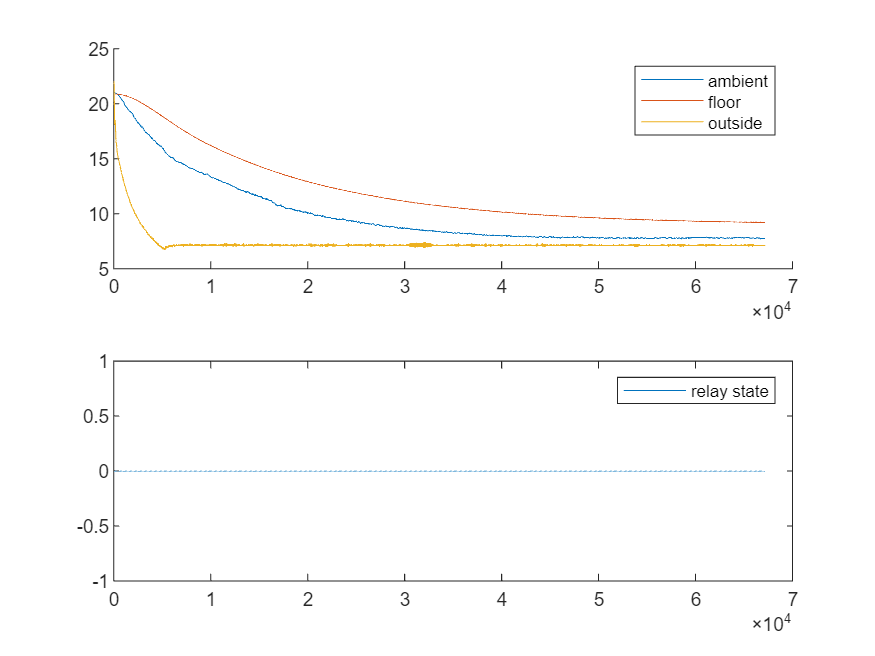

figure("Name", "Active Cooling");
tiledlayout(2,1);
nexttile;
hold on;
plot(AC_data.temperature_ambient);
plot(AC_data.temperature_floor);
plot(AC_data.count, AC_data.AirInHouse__CG4_/10);
legend("ambient", "floor", "outside");
nexttile;
plot(AC_data.regulation_relay_state);
legend("relay state");
hold off;

## Heating data

baselog_He_file = data_dir + "\BaseLog-2024-03-20T100744-Heating.csv";
baselog_He_data = loadDataSource(baselog_He_file);

modblog_He_file = data_dir + "\ModbusGUI-Log-2024-03-20T100738-Heating.csv";
modblog_He_data = loadDataSource(modblog_He_file);
He_data = innerjoin(modblog_He_data,baselog_He_data,"LeftKeys","TimeStamp","RightKeys","timestamp")

He_data = 12316×32 table
           TimeStamp           regulation_relay_state    regulation_setpoint    regulation_output    pwm_info_pwm_step    pwm_info_period_length_seconds    pwm_info_pulse_counter    pwm_info_period_length_seconds_1    pwm_info_pulse_target    temperature_floor    temperature_ambient    count    sec    nu     RefFloor__CG0_    RefRoom__CG1_    RegRoom180cm__CG2_    RefTopFloor__CG3_    AirInHouse__CG4_    AirOutHouse__CG5_    TS0    TS1    TS2    TS3    TS4    TS5    Krap_Short    Krap_byte    <

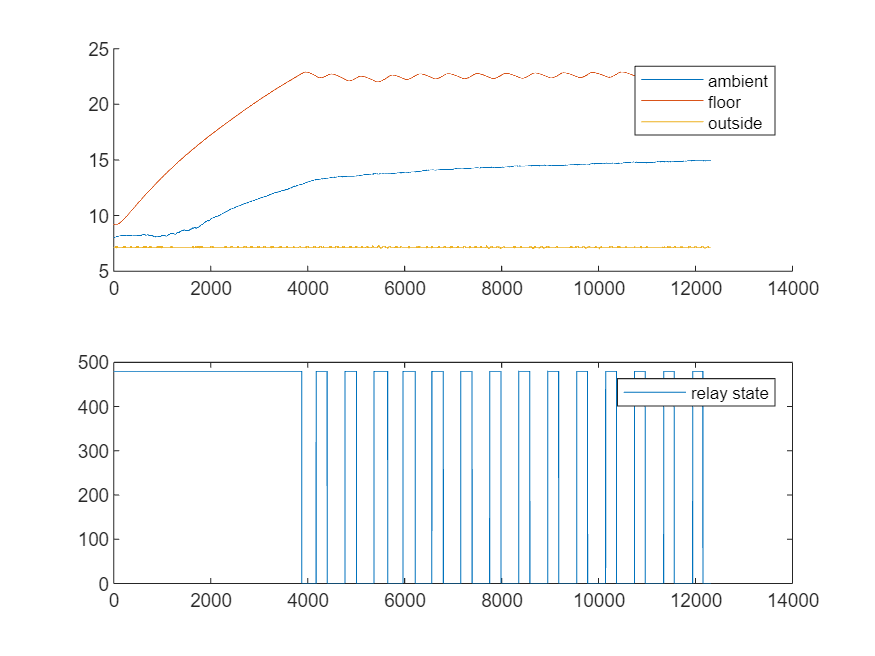

figure("Name","Heating");
tiledlayout(2,1);
nexttile;
hold on;
plot(He_data.temperature_ambient);
plot(He_data.temperature_floor);
plot(He_data.AirInHouse__CG4_/10);
legend("ambient", "floor", "outside");

nexttile;
plot(He_data.regulation_relay_state*480);
legend("relay state");
hold off;

## Combine active cooling with heating

T_a = vertcat(AC_data.temperature_ambient, He_data.temperature_ambient);
T_f = vertcat(AC_data.temperature_floor, He_data.temperature_floor);
T_o = vertcat(AC_data.AirInHouse__CG4_/10, He_data.AirInHouse__CG4_/10);
u = vertcat(AC_data.regulation_relay_state, He_data.regulation_relay_state*480);
t = vertcat(AC_data.TimeStamp, He_data.TimeStamp);

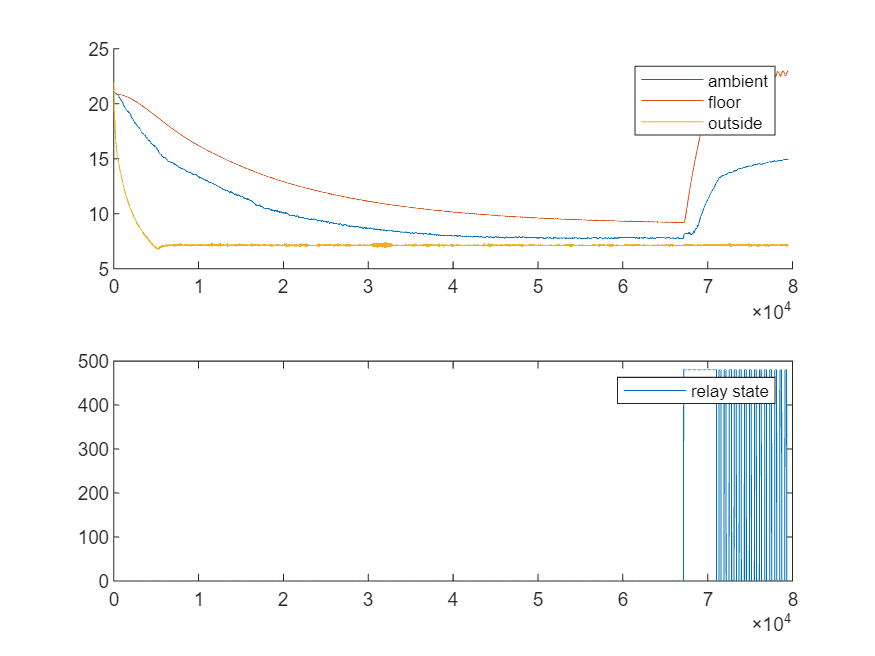

figure("Name","Combine");
tiledlayout(2,1);
nexttile;
hold on;
plot(T_a);
plot(T_f);
plot(T_o);
legend("ambient", "floor", "outside");

nexttile;
plot(u);
legend("relay state");
hold off;

% Generate the main training dataset
fullset = table(t, u, T_f, T_a, T_o);

## Start fitting with a grey model

It is better to use this whole set of "test 6" to train the model and use other "test x" to validate it.

split_idx = 74690;
fit_set = fullset(1:split_idx,:);
fit_data = iddata([fit_set.T_f, fit_set.T_a], ...
    fit_set.u, ...
    1, ...
    'TimeUnit', 'seconds', ...
    'InputName', {'Electrical power'}, ...
    'OutputName', {'Floor temperature', 'Ambient temperature'});

val_set = fullset(split_idx+1:end,:);
val_data = iddata([val_set.T_f, val_set.T_a], ...
    [val_set.u, val_set.T_o], ...
    1, ...
    'TimeUnit', 'seconds', ...
    'InputName', {'Electrical power', 'Outside temperature'}, ...
    'OutputName', {'Floor temperature', 'Ambient temperature'});


The physics model of Narnia, an enclosed chamber, is:


$$\pmatrix{
  \dot{T}_A \cr
  \dot{T}_F \cr
  \ddot{T}_A
} = \pmatrix{
  0 & 0 & 1 \cr
  -\frac{kA}{d m_F C_F} & 0 & -\frac{m_A C_A}{m_F C_F} \cr
  0 & 0 & 0
} \pmatrix{
  T_A \cr
  T_F \cr
  \dot{T}_A
} + \pmatrix{
  0 \cr
  \frac{1}{m_F C_F} \cr
  0
}u + \pmatrix{
  0 \cr
  \frac{kA}{d m_F C_F} \cr
  0
}T_O$$



$$\Leftrightarrow \pmatrix{
  \dot{T}_A \cr
  \dot{T}_F \cr
  \ddot{T}_A
} = \pmatrix{
  0 & 0 & 1 \cr
  -\frac{kA}{d m_F C_F} & 0 & -\frac{m_A C_A}{m_F C_F} \cr
  0 & 0 & 0
} \pmatrix{
  T_A \cr
  T_F \cr
  \dot{T}_A
} + \pmatrix{
  0 & 0\cr
  \frac{1}{m_F C_F} & \frac{kA}{d m_F C_F} \cr
  0 & 0
} \pmatrix{
  u \cr
  T_O}$$



$$\textbf{y} = \pmatrix{0 & 1 & 0}\textbf{x}$$


Let $\text{par(1)} = \frac{kA}{d};
~\text{par(2)} = \frac{1}{m_F C_F};
~\text{par(3)} = m_A C_A$

par = abs(randn(3,1));
aux = {};
Ts = 0; % Continuous-time model
model_init = idgrey('myfunc',par,'c',aux,Ts);
opt = greyestOptions('InitialState',[fit_set.T_a(1); fit_set.T_f(1); 0],...
    'DisturbanceModel','model',...
    'Display','on');

[model_est, x0] = greyest(fit_data, model_init, opt);

Error using iddata/greyest
The number of inputs and outputs of the model must match that of the data.

## Prepare validation data

baselog_NC_file = data_dir + "\BaseLog-2024-03-20T134102-NaturalCooling.csv";
baselog_NC_data = loadDataSource(baselog_NC_file);
modblog_NC_file = data_dir + "\ModbusGUI-Log-2024-03-20T134038-NaturalCooling.csv";
modblog_NC_data = loadDataSource(modblog_NC_file);
NC_data = innerjoin(modblog_NC_data,baselog_NC_data,"LeftKeys","TimeStamp","RightKeys","timestamp")

figure("Name","Natural Cooling");
tiledlayout(2,1);
nexttile;
hold on;
plot(NC_data.temperature_ambient);
plot(NC_data.temperature_floor);
plot(NC_data.AirInHouse__CG4_/10);
legend("ambient", "floor", "outside");

nexttile;
plot(NC_data.regulation_relay_state*480);
legend("relay state");
hold off;
val_data_2 = iddata([NC_data.temperature_floor, NC_data.temperature_ambient], ...
    [NC_data.regulation_relay_state*480, NC_data.AirInHouse__CG4_/10], ...
    1, ...
    'TimeUnit', 'seconds', ...
    'InputName', {'Electrical power', 'Outside temperature'}, ...
    'OutputName', {'Floor temperature', 'Ambient temperature'});

## Validate estimated models

compare(val_data_2, nlarx10)